# Load data

This script loads a sounding from the worspace and converts it to a simulink bus for the model. It also plots the sounding. The script runs automatically on startup. To choose another sounding, run the relevant section in the parse_sounding_live.mlx script.

## Extract necessary data for Simulink

% Load one sounding from the workspace
load('sounding.mat');

% Load sounding bus
load("sounding_bus.mat");

% Convert the sounding object into a Simulink bus object of the type
% sounding_bus (defined in sounding_bus.mat)

numLevels = length(reduced_sounding.derived.REPGPH); % This variable needs to be
                                                     % present in the workspace
sounding_data_bus.numLevels = numLevels;
sounding_data_bus.zi = reduced_sounding.mixedLayerHeight;
sounding_data_bus.LCL = reduced_sounding.LCLheight;
sounding_data_bus.REPGPH = reduced_sounding.derived.REPGPH;
sounding_data_bus.PRESS = reduced_sounding.derived.PRESS;
sounding_data_bus.TEMP = reduced_sounding.derived.TEMP/10;
sounding_data_bus.PTEMP = reduced_sounding.derived.PTEMP/10;
sounding_data_bus.VTEMP = reduced_sounding.derived.VTEMP/10;
sounding_data_bus.VAPPRESS = reduced_sounding.derived.VAPPRESS/10;
sounding_data_bus.SATVAP = reduced_sounding.derived.SATVAP/10;
sounding_data_bus.REPRH = reduced_sounding.derived.REPRH/10;

## Plot atmospheric profiles

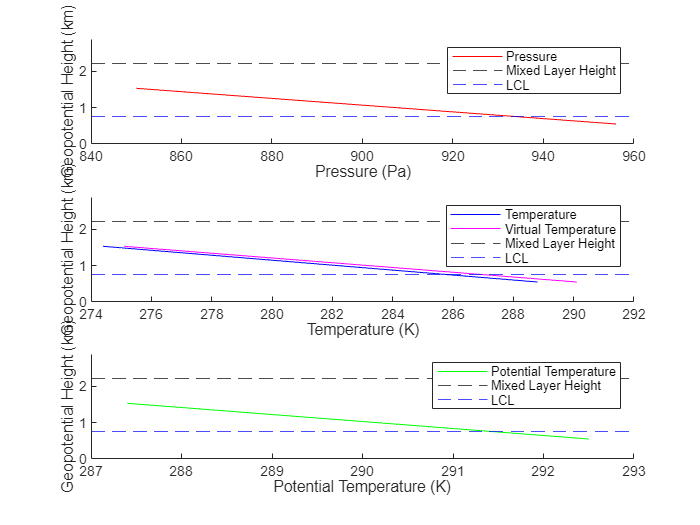

% Plot pressure, temperature, potential temperature and virtual 
% temperature profiles over geopotential height. The geopotential 
% height is used as the vertical coordinate.
plot_sounding(reduced_sounding, 1.3);